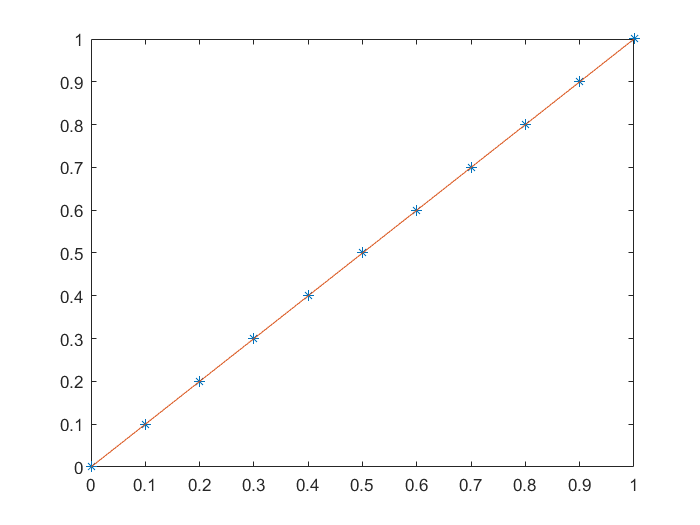

clc,clear,close all
xn = 1;x0 = 0;
n = 10;
h = (xn-x0)/n;
x = (x0+h):h:(xn-h);
A0 = [1,zeros(1,n)];
A1 = [diag(ones(1,n-1)).*(2-2*x.^2*h) , zeros(n-1,2)];
A2 = [zeros(n-1,1),diag(ones(1,n-1)).*(-4-4*h^2*x) , zeros(n-1,1)];
A3 = [zeros(n-1,2),diag(ones(1,n-1).*(2+2*x.^2*h))];
A4 = [zeros(1,n),1];
A = [A0;A1+A2+A3;A4];
b = [zeros(n,1);1];
y = A\b;
plot(x0:h:xn,y,'*')

syms y(t)
Dy = diff(y,t);
cond = [y(0) == 0,y(1)==1];
f = dsolve(diff(y,t,2) + 2*t^2*diff(y,t,1) - 2*t*y ==0,cond);
f = matlabFunction(f);
x = x0:h:xn;
hold on
plot(x,f(x))
hold off

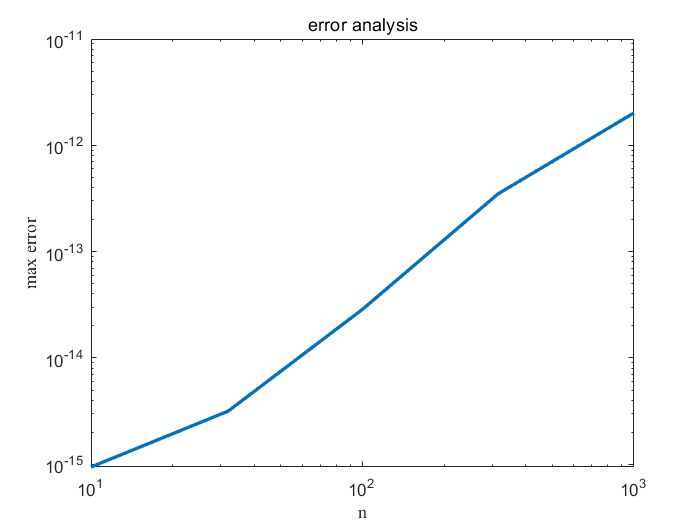


m = zeros(1,6);
for i= 1:6
    n = round(10^(0.5+i/2));
    h = (xn-x0)/n;
    x = (x0+h):h:(xn-h);
    A0 = [1,zeros(1,n)];
    A1 = [diag(ones(1,n-1)).*(2-2*x.^2*h) , zeros(n-1,2)];
    A2 = [zeros(n-1,1),diag(ones(1,n-1)).*(-4-4*h^2*x) , zeros(n-1,1)];
    A3 = [zeros(n-1,2),diag(ones(1,n-1).*(2+2*x.^2*h))];
    A4 = [zeros(1,n),1];
    A = [A0;A1+A2+A3;A4];
    b = [zeros(n,1);1];
    y = A\b;
    
    x = x0:h:xn;
    
    error = abs((y'-f(x)));
    my_error = error(round(n/2));
    m(i) = my_error;
end
i= 1:6;
n = round(10.^(i/2));
loglog(n,m,"LineWidth",2)
xlim([10,1000])
title('error analysis')
xlabel('n','Fontname','Times New Roman')
ylabel('max error','Fontname','Times New Roman')